% singleConnectedRegionSegmentationUseWatershedTest

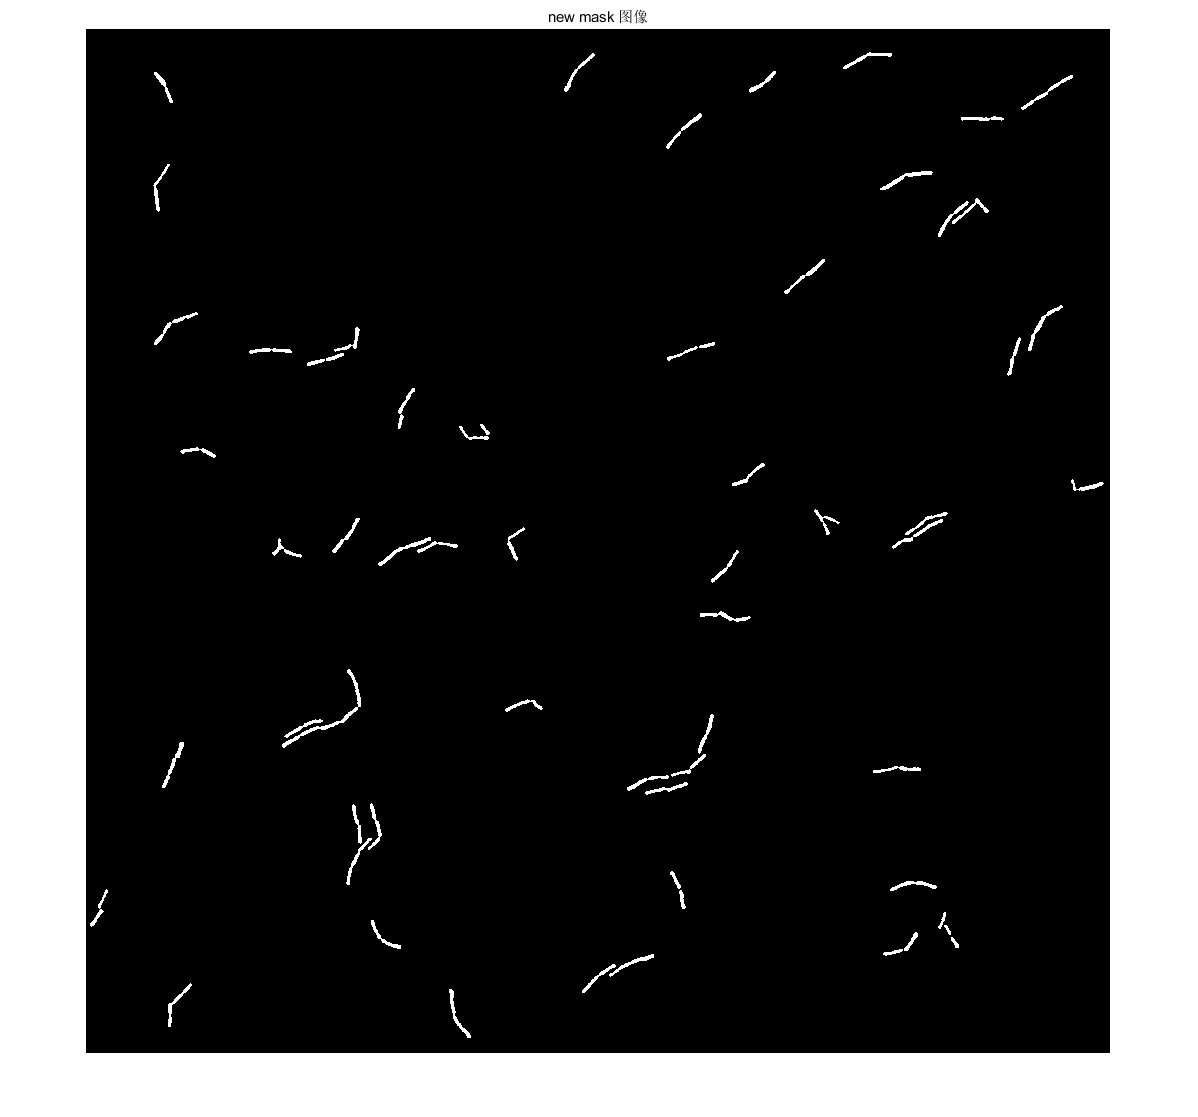

% testSingleConnectedRegionUseWatershed

% image=import_tiff_stack('E:\2019-12-26 PAO1_deltpslpelfliC_IP32_100x ys\field0004\BF\imageBF04000.tif');


% [bw,~]=myImageProcessing_cBFys(I_eq,'w');
% imshow(bw)

I=false(2048,2048);
stats = regionprops(bw,'Centroid','MajorAxisLength','MinorAxisLength','PixelIdxList','PixelList');
for i=1:numel(stats)
    if numel(stats(i).PixelIdxList)>=500
        I(stats(i).PixelIdxList  )=1;
    end
end
imshow(I),title('new mask 图像')

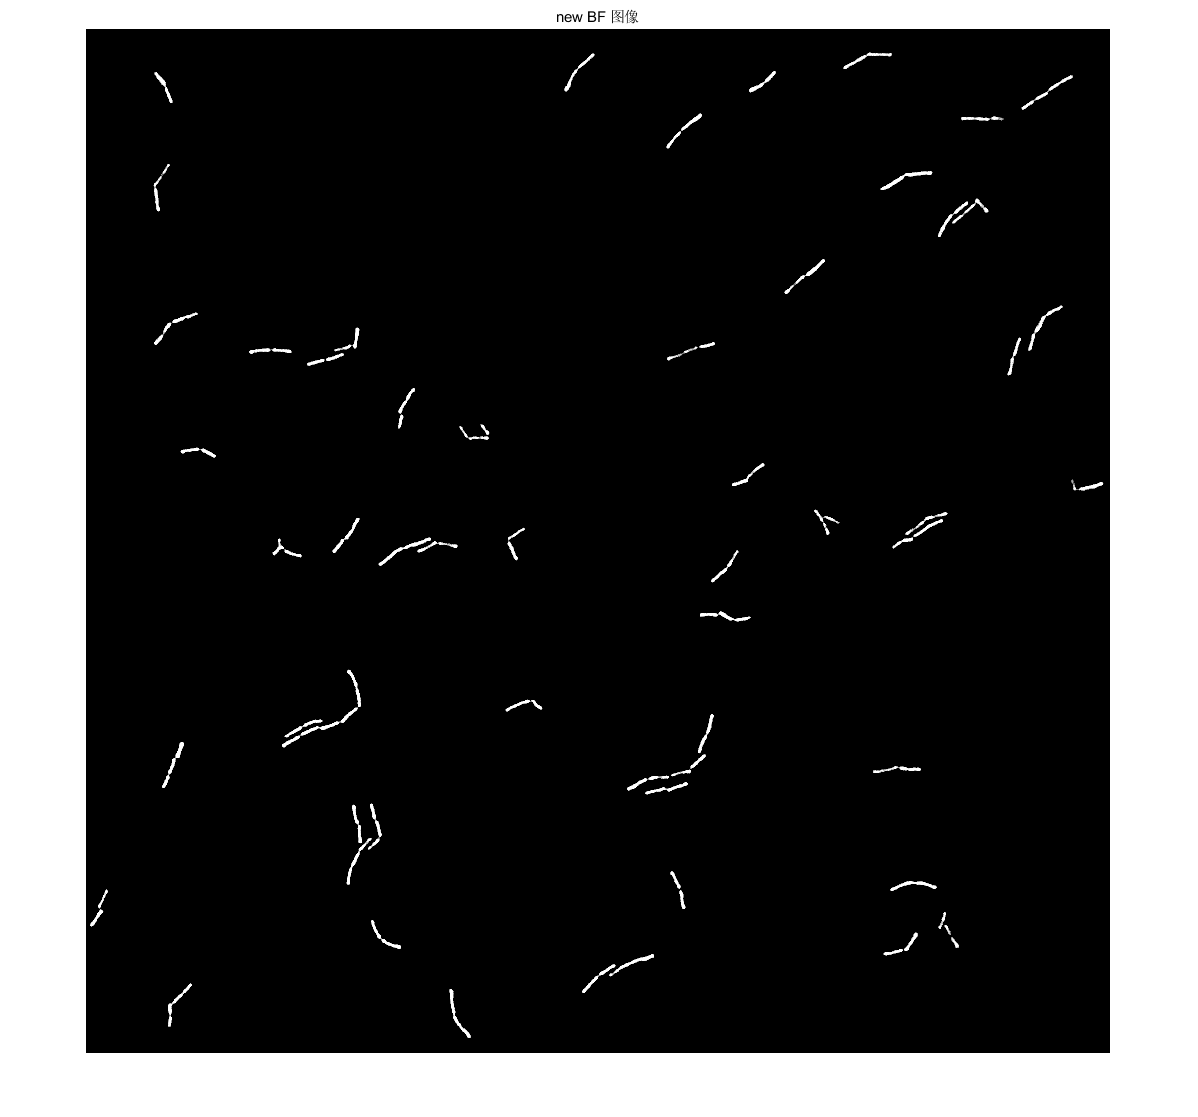


imageNew=imimposemin(image, ~I);
imshow(imageNew),title('new BF 图像')

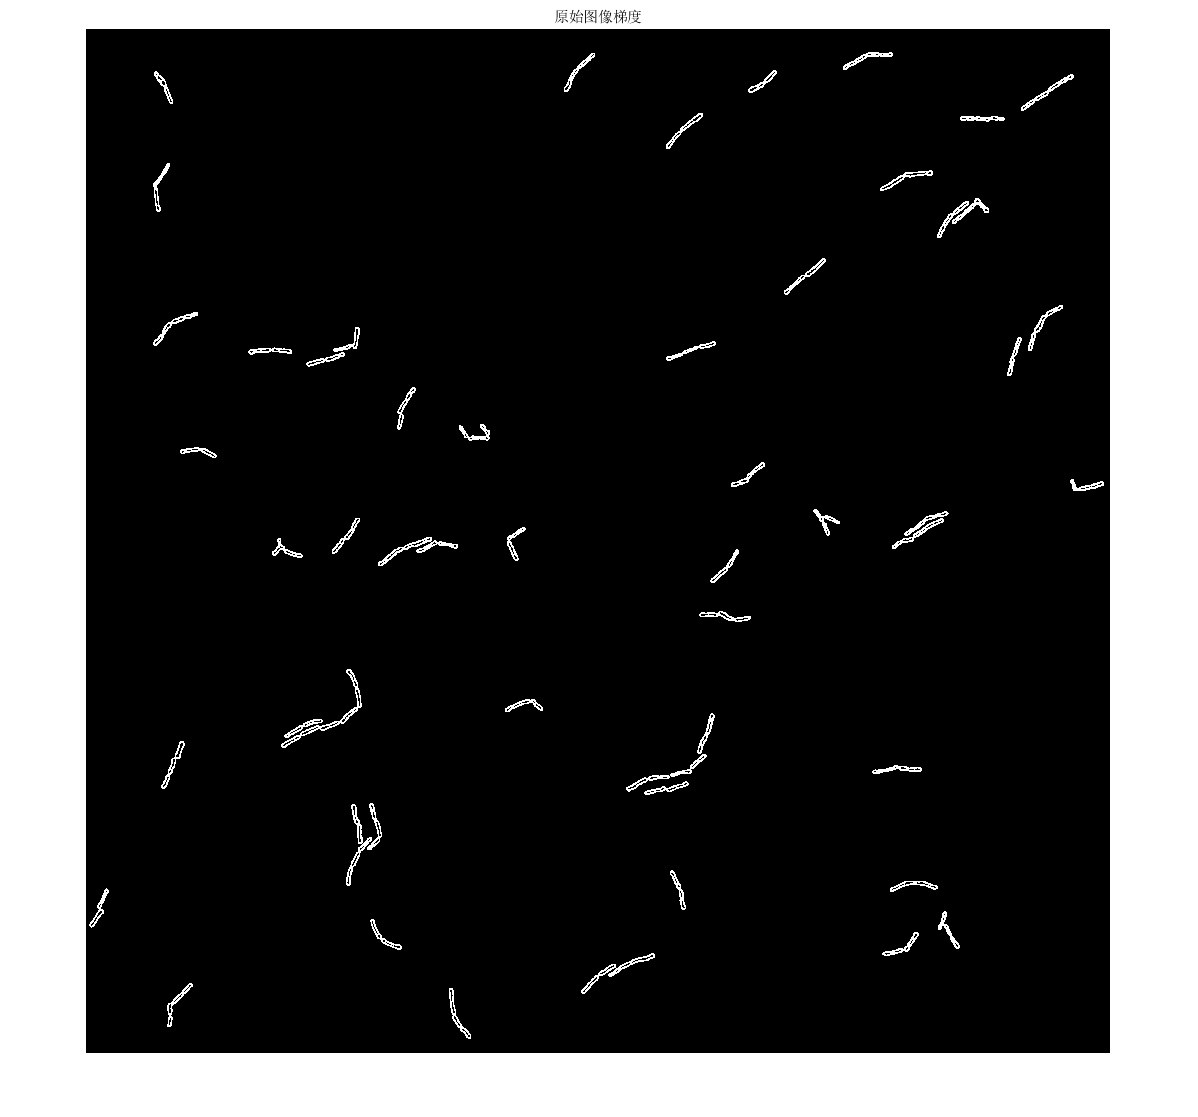

% 
% I_eq=image;
% I_eq_c = imcomplement(I_eq);
% imshow(I_eq_c)
% 
% I_mod1 = imimposemin(I_eq_c, I);
% imshow(I_mod1,[0,50])
% 
% L1 = watershed(I_mod1);
% imshow(L1)
% imshow(label2rgb(L1))
% L1_1=imbinarize(L1,2/2^16);
% imshow(L1_1)


g=imgradient(imageNew);
% imshow(image),title('原始BF图像')
imshow(g),title('原始图像梯度')

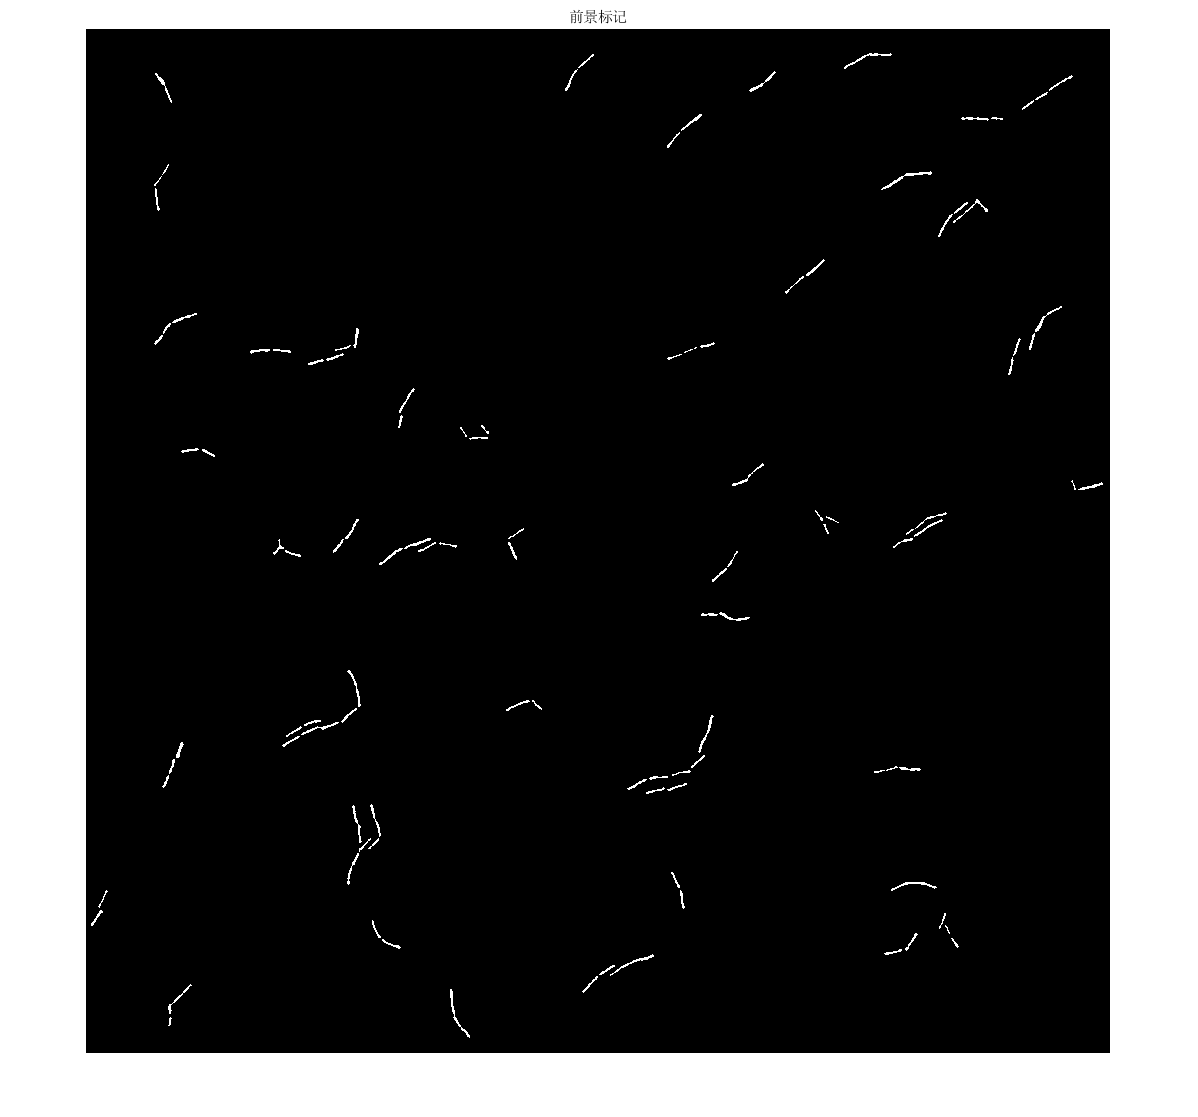


% 2. Compute foreground markers.  These are connected blobs of pixels withineach of the objects.
im=imerode(I,strel('rectangle',[3 3]));
% imshow(image)
imshow(im),title('前景标记')

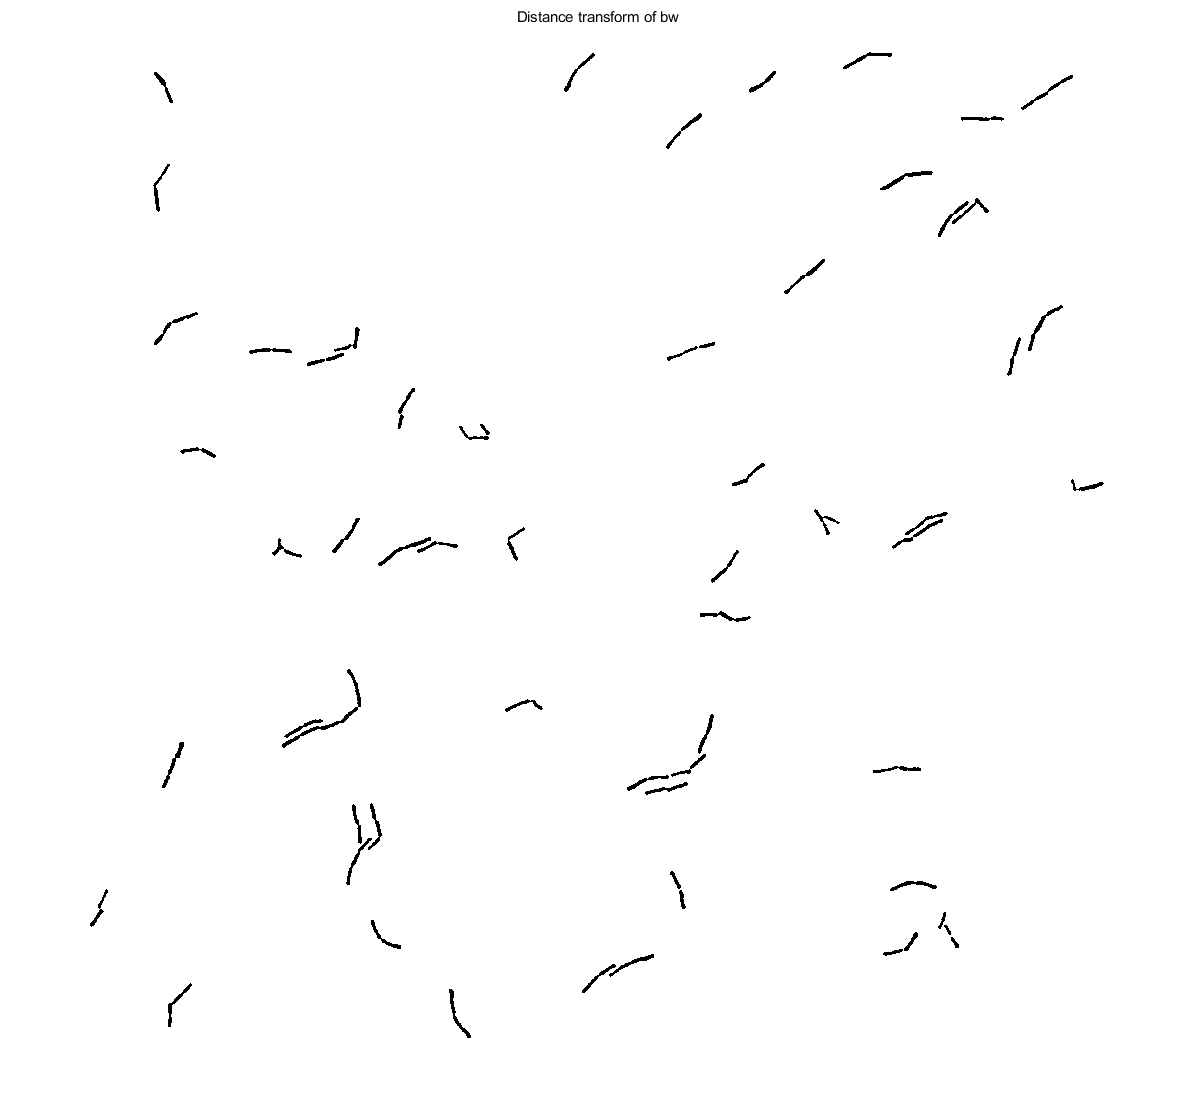


%% 3. Compute backgroundmarkers.  These are pixels that are notpart of any object.
D = bwdist(I);
imshow(D),title('Distance transform of bw')

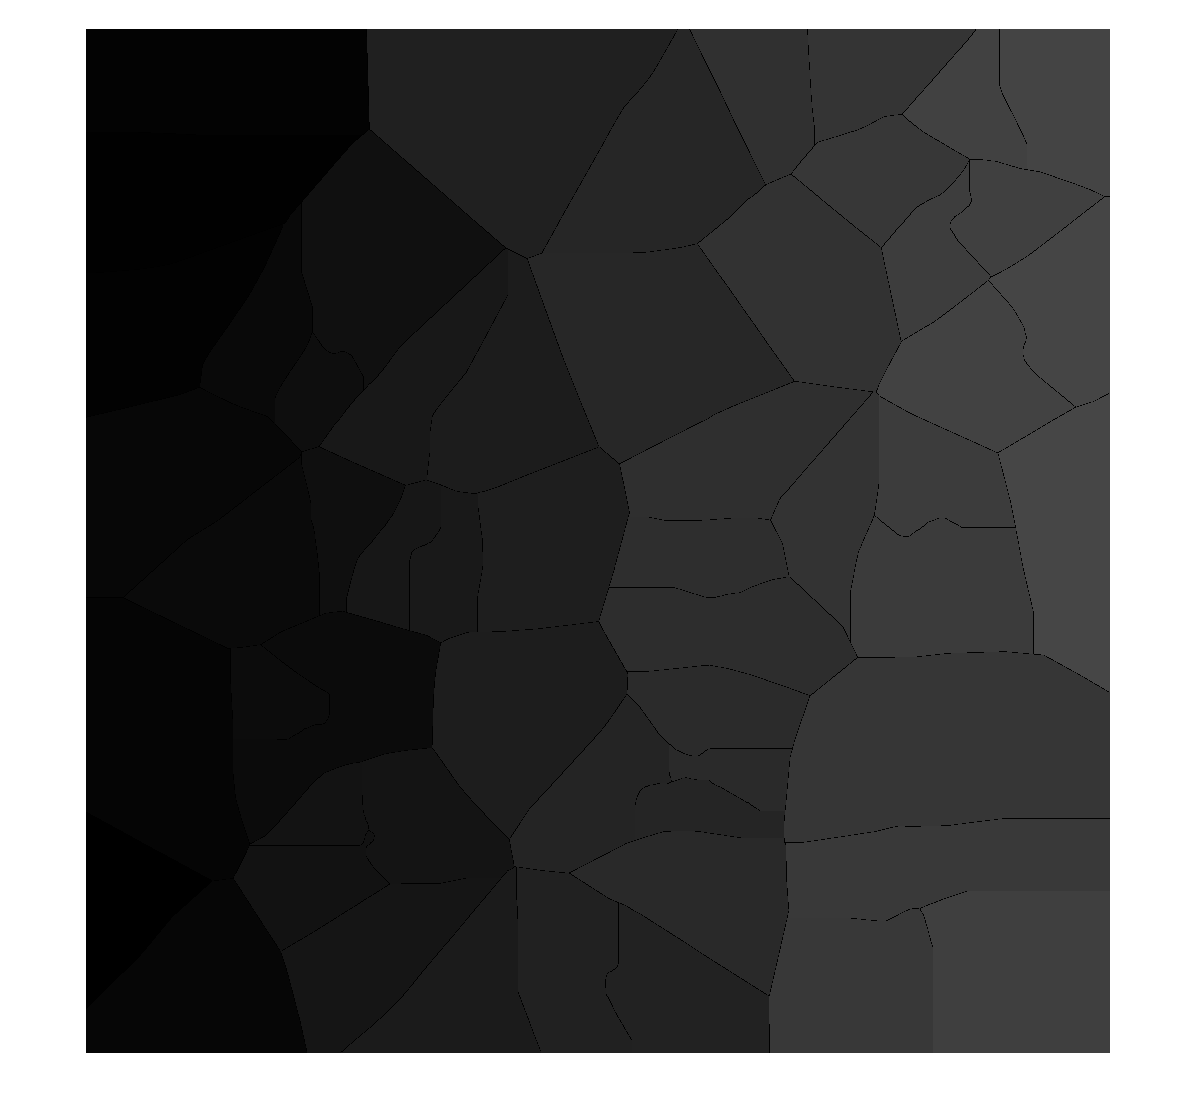

Lim=watershed(D);
imshow(Lim,[1,200])

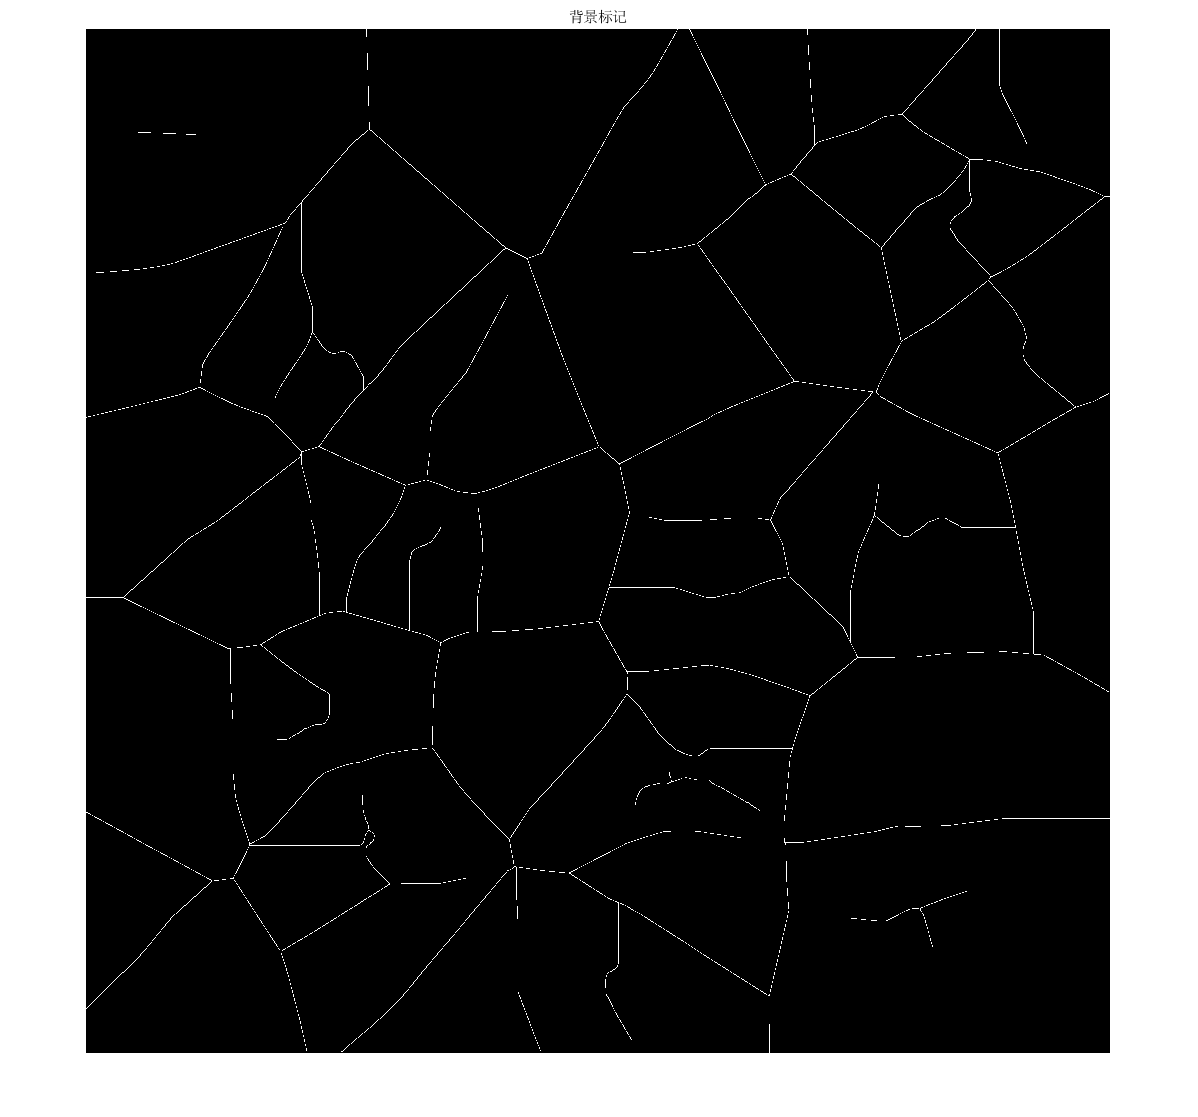

em=Lim==0;
imshow(em),title('背景标记')

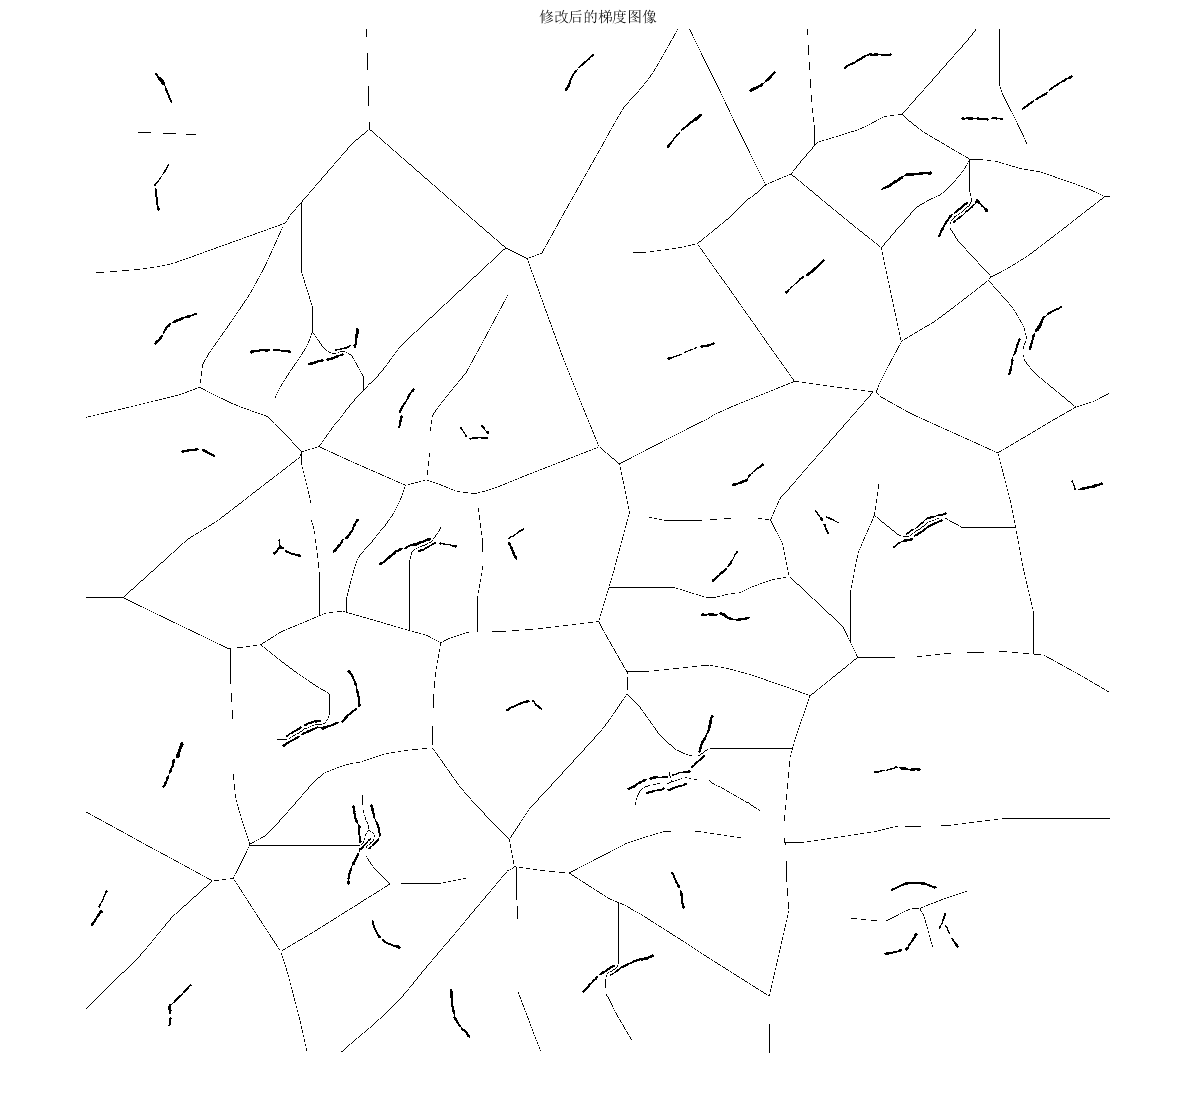


%% 4. Modify the segmentation function sothat it only has minima at the foreground and background marker locations.

g2=imimposemin(g,im | em);
imshow(g2),title('修改后的梯度图像')

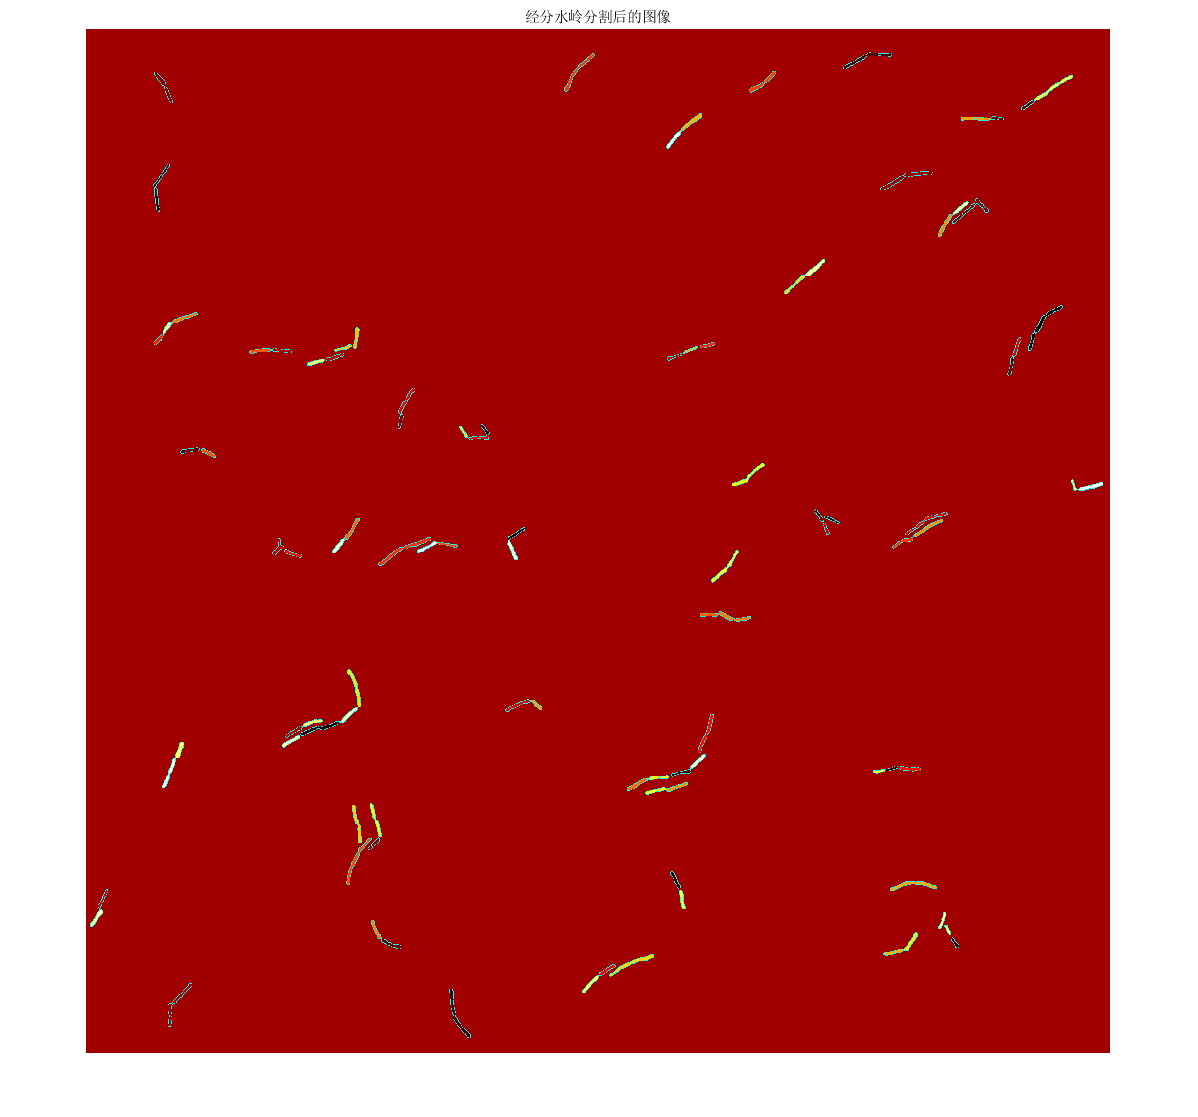


%% 5. Compute the watershedtransform of the modified segmentation function.
% 对修改后的梯度图像进行分水岭分割
L2=watershed(g2);

%% 6. 显示分水岭的分割结果
rgb2=label2rgb(L2, 'hot', 'c', 'shuffle');
figure
% imshow(I),title('原始mask图像')
imshow(rgb2),title('经分水岭分割后的图像')

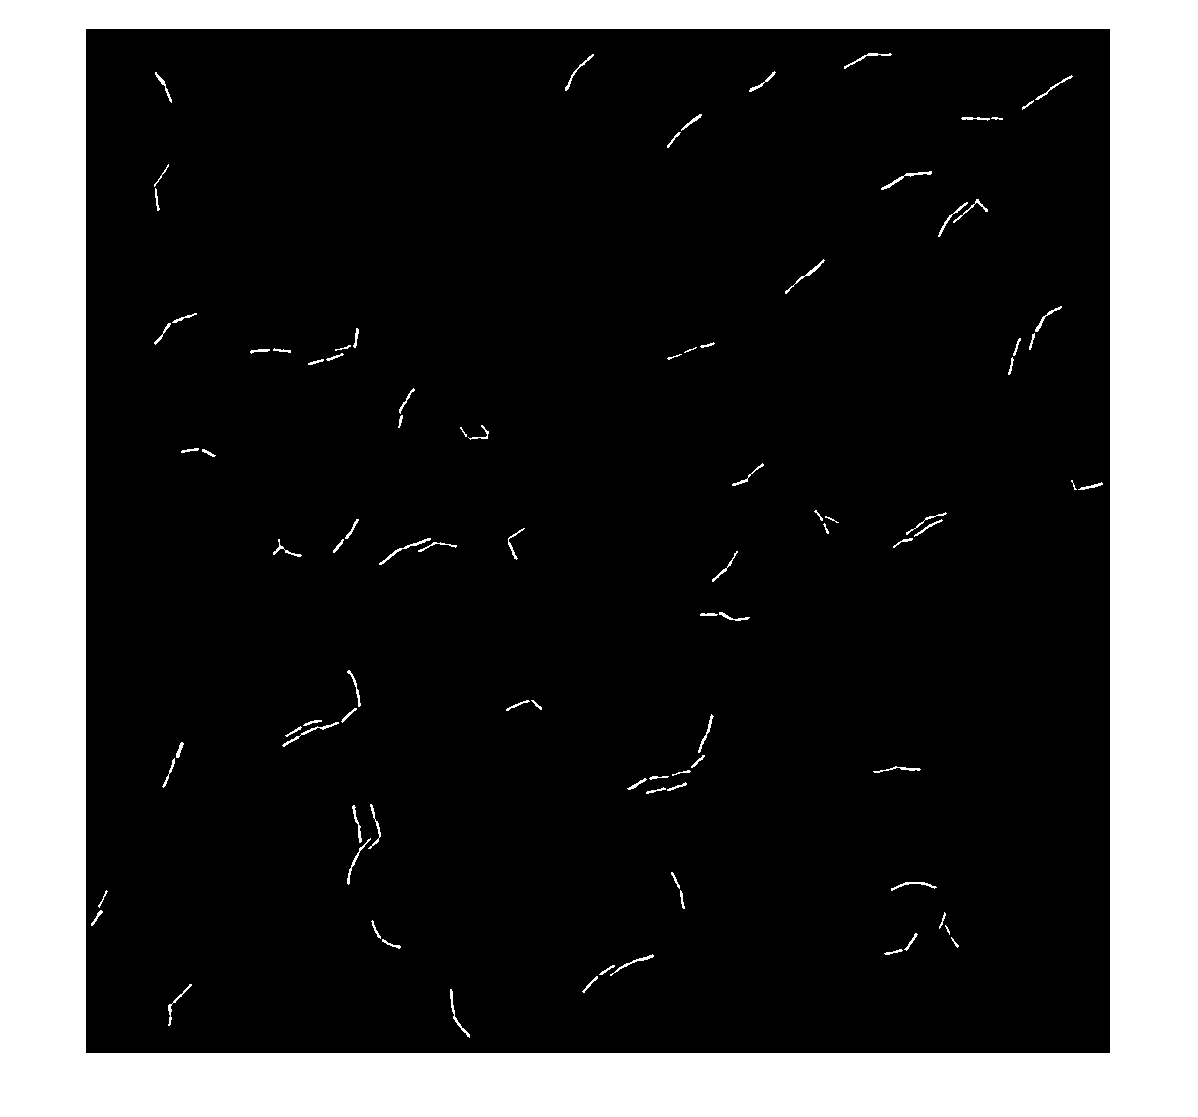


L3=imbinarize(L2,'adaptive');
imshow(L3)

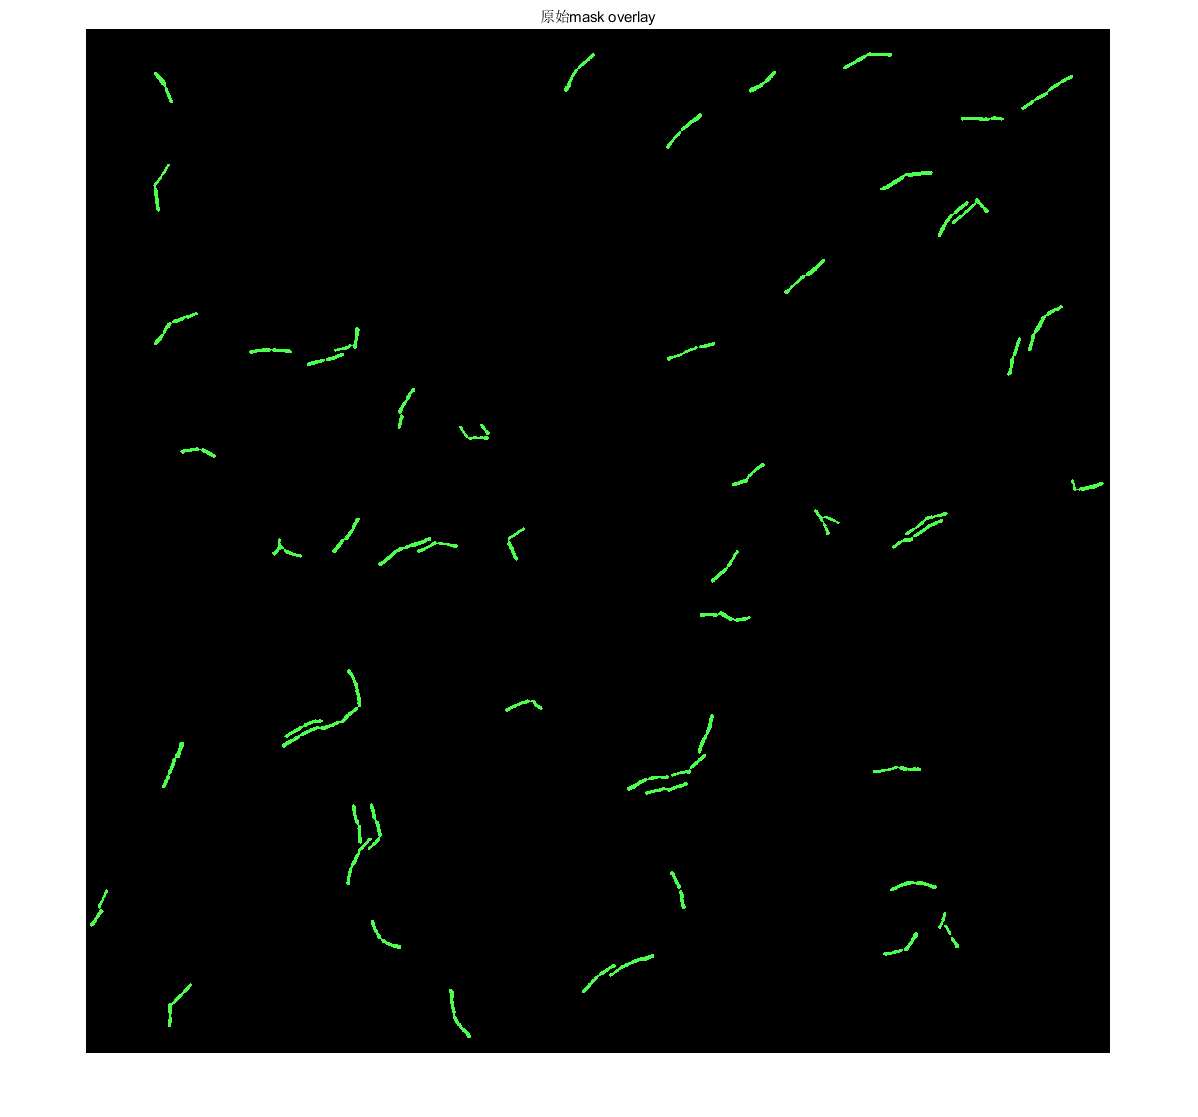


overlay1 = imoverlay(imageNew, I, [.3 1 .3]);
imshow(overlay1), title('原始mask overlay')

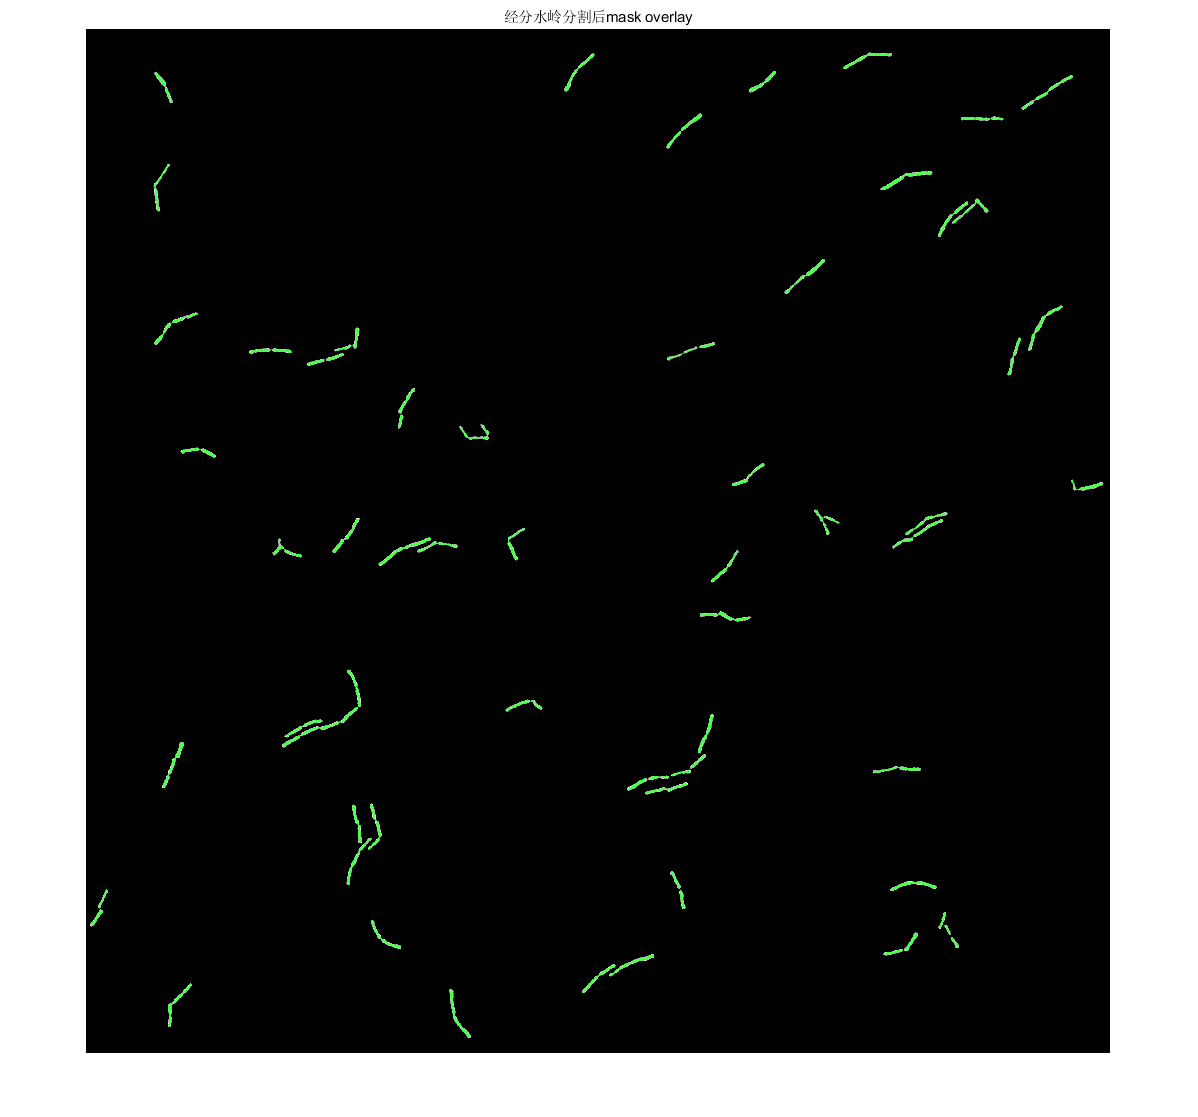


overlay2 = imoverlay(imageNew, L3, [.3 1 .3]);
imshow(overlay2),title('经分水岭分割后mask overlay')